# Hierarchical Risk Parity Test File

#### Author: Nina Matthews

#### Project: Masters Dissertation - Blending Mean-Variance and Hierarchical Risk Parity using Time- and Market-Conditioned Flexible Probabilities

#### Last edit: 25/02/2023

#### Supervisor: A/Prof. Tim Gebbie

**Resouces Used: **The MathWorks, Inc. (2019)  &  Marcos Lopez De Prado (2016) (*See reference list below)*

## **Purpose:**

This file tests *Fn_HRP_estimate() *using dummy data of a 10 asset case. 

## Data:

The data of the 10 assset case is based on the simulated data that was generated in De Prodo's python code chunk that he defined in his 2016 paper. However, in the subsequent years, Python made a fundemental change in how their random generator functions work so the data was not fully retievable. This issue was overcome by sourcing the data from Kipnis when he replicated the data in 2017 before the change was made.  

## Validation:

The functions and additional code is validated by using the test data as well as output generatied using the R programming language to compare output weights. The results show that both languages produce the same output, and both match De Prado's results.

% Set source paths
addpath("/Users/Ninamatthews/Desktop/MASTERS/DISSERTATION Code/3_Data")

## Test

#### Load data

The dataset is simulated that some assets are closely correlated.

assetcov_csv = readtable('Kipnis_covMat.csv')

assetcov_csv = 10×10 table
        V1            V2            V3             V4             V5            V6            V7            V8            V9           V10    
    __________    __________    ___________    ___________    __________    __________    __________    __________    __________    __________

        1.0006    -0.0030505       0.010033       -0.01076    -0.0050365     0.0087626        0.9982    -0.0013932    -0.0012545     -0.009366
    -0.0030505         1.009      0.0086138      0.0073345    -0.0094927      0.013032    -0.0094207     -0.015346        1.0105        1.0133
      0.010033     0.0086138         1.0007    -0.00063789  

Visualise data using a heatmap. Note: same profile as seen through R but the ordering is 1 to 10 descending whilst this is reversed when displayed in R.

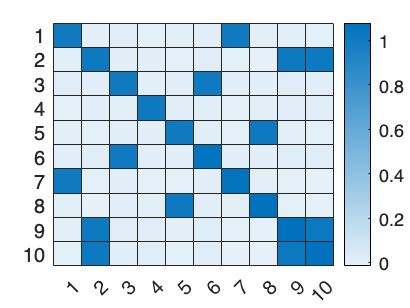

% Import data and convert to matrix
cov_10_asset = readmatrix('Kipnis_covMat.csv');
cov = (cov_10_asset); % Flip columns and transpose
% Display heatmap
heatmap(cov);

Apply our HRP function.

wgtHRP = Fn_HRP_estimate(cov_10_asset);

Output confirmed against R output as well as De Prado's results in his principle paper on HRP.

**MV for comparision **

% initiallising portfolio object, with mean, covar, lower, upper bound and
% budget constraints 
pMV = Portfolio('AssetCovar', assetCovar, 'AssetMean', mean(assetRetn_csv), 'lb', 0, 'ub', 1, 'budget', 1);

Unrecognized function
or variable
'assetCovar'.

wgtMV = estimateFrontierLimits(pMV, 'min');

**Comparision Visualization**

Here you can visualize the resulting allocations from the two strategies. 

a = num2cell(1:nAssets);
labels = cellfun(@(x) num2str(x),a', 'UniformOutput', false);
ax1 = subplot(1,2,1);
pie(ax1,wgtHRP(wgtHRP>0),labels(wgtHRP>0))
title(ax1,'HRP Allocation','Position', [-0.05, 1.6, 0]);

ax2 = subplot(1,2,2);
pie(ax2,wgtMV(wgtMV>0),labels(wgtMV>0))
title(ax2,'Mean Variance Allocation' ,'Position', [-0.05, 1.6, 0]);
wgtTable = array2table([wgtHRP, wgtMV], 'VariableNames', {'HRP', 'MeanVariance'})

You can see that HRP produces a much more diversified allocation as compared to Mean-Variance framework. Next step, you can backtest the HRP strategy against others and extract their performance metrics. 

#### Reference

- Lopez de Prado, Marcos. "Building diversified portfolios that outperform out-of-sample", Journal of Portfolio Management, 2016 

- [https://www.mathworks.com/help/stats/hierarchical-clustering.html](https://www.mathworks.com/help/stats/hierarchical-clustering.html)

- [https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html](https://www.mathworks.com/help/finance/asset-allocation-and-portfolio-optimization.html)

- [https://en.wikipedia.org/wiki/Risk_parity](https://en.wikipedia.org/wiki/Risk_parity)